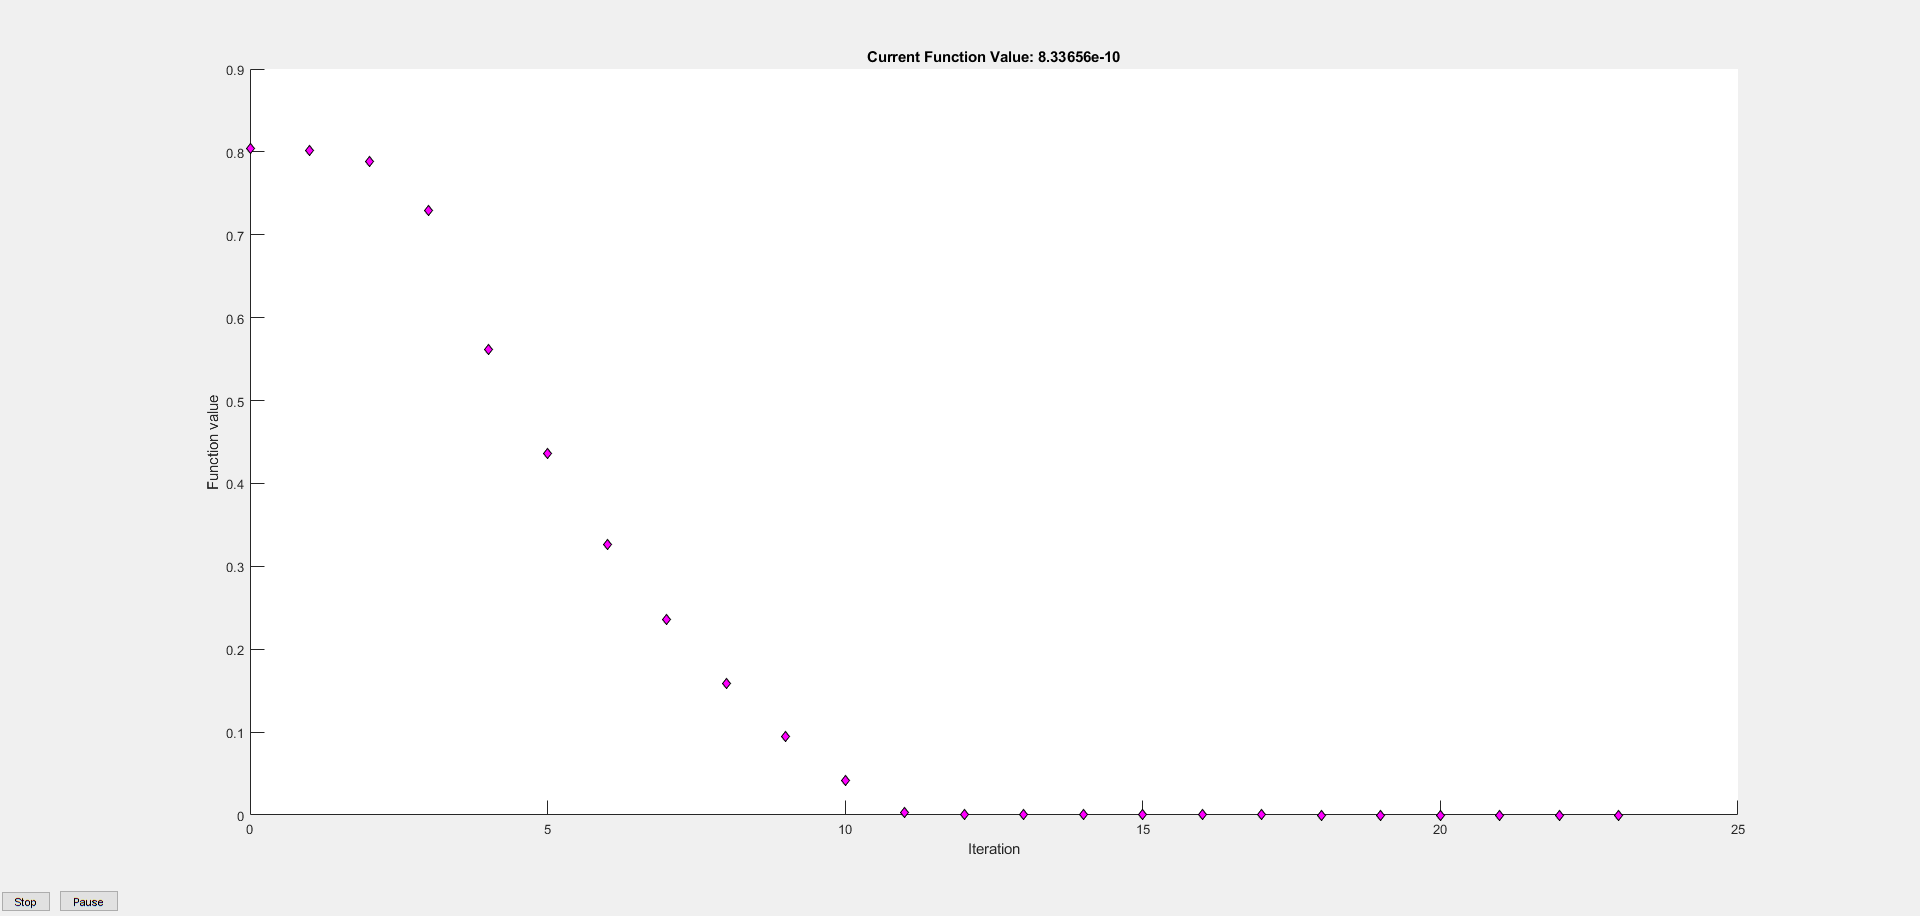


Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.



clear all
addpath(genpath("UtilityFunctions"))
global p1 R xcyc t_target
p1 = [0.125099992047280; 0];
p2 = [ 0.571728491645258;
   0.10000000000000];
p3 = [1.0183569912432361;
     0];
t_target = 0.234684820497692;
 [R,xcyc] = fit_circle_through_3_points([p1,p2,p3]');
 options = optimoptions('fmincon','MaxFunctionEvaluations',10000,'OptimalityTolerance',1e-15,'Display','final-detailed','PlotFcn','optimplotfval');
[g_star,cost_star] = fmincon(@ode_cost,9.81,[],[],[],[],[],[],[],options);


g_param = g_star;
odeoptions = odeset('RelTol', 1e-10, 'AbsTol', 1e-10,'Events',@pend_event);
[tout,xout] = ode45(@pendulum,[0,30],[p1(1),p1(2),0,0],odeoptions);

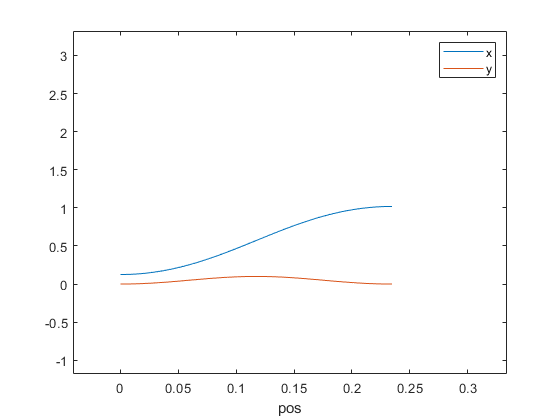

figure
plot(tout,xout(:,1),tout,xout(:,2))
legend('x','y')
xlabel('time')
xlabel('pos')

xlim([-0.041 0.334])
ylim([-1.18 3.32])

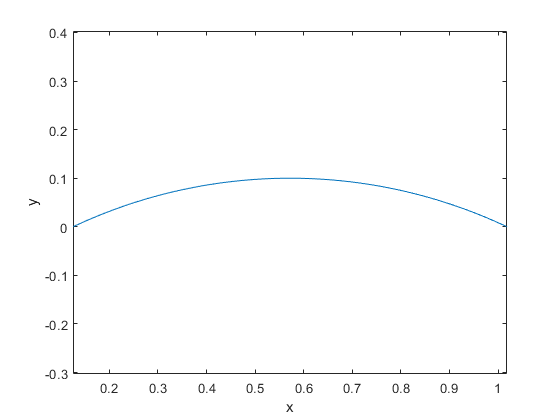

figure
plot(xout(:,1),xout(:,2))
xlabel('x')
ylabel('y')
axis equal

function dx = pendulum(t, x)
%PENDULUM_M  A pendulum system.
global g_param R xcyc
%   Copyright 2005-2006 The MathWorks, Inc.

% Output equation.
y = x(1:2);                                  
y0 = x(2)-xcyc(2);
x0 = x(1)-xcyc(1);
% State equations.

dx = [x(3:4);                             
      [0;g_param]-1/R^2*(g_param*y0+x(3)^2+x(4)^2)*[x0;y0]];
end

function [value,isterminal,direction] = pend_event(t,y)
    value = y(3);
    direction = -1;
    isterminal = true;
end

function my_cost = ode_cost(g)
    global g_param p1 xcyc t_target
    g_param = g;
    odeoptions = odeset('RelTol', 1e-10, 'AbsTol', 1e-10,'Events',@pend_event);
    [tout,xout] = ode45(@pendulum,[0,30],[p1(1),p1(2),0,0],odeoptions);
    my_cost = abs(t_target-tout(end));
end